%% Experimental Methods HW #2 Dan Lawson

## Problem 1 Error Propogation Analysis

% Given Information
T = [14.22, 14.31, 14.34, 14.23, 14.20, 14.32, 14.19]; % sec for 10 periods
L = 0.503; % m 
conf = 0.9;

% Given Uncertainties 
sig_L = 0.0005; % [m] (uncertainty of 0.5 mm) 
sig_T = 0.01; % [S] Reading Uncertainty 

% Uncertainty calc
T_bar = mean(T);
T_std = (t_value(conf, length(T) - 1)*std(T))/sqrt(length(T)); % Quantification of random error in T

eT = sqrt(T_std^2 + sig_T^2); % propagation of reading and random error

g_bar = 400 * pi^2 * L * T_bar^(-2);
% See notes for this problem, mostly done in class 

% Define the error_prop_xm_yn and t_value functions if not defined previously
error_prop_xm_yn = @(x, n, sig_x, y, m, sig_y) sqrt((n * sig_x / x)^2 + (m * sig_y / y)^2);
t_value = @(conf, df) tinv((conf + 1) / 2, df);

eg = g_bar * error_prop_xm_yn(L, 1, sig_L, T_bar, -2, eT);
eg_total = eg;
%t_value(conf, length(T) - 1) *
fprintf('The mean value of g: %.3f pm %.3f at 90%%\n', g_bar, eg_total);

The mean value of g: 9.767 pm 0.065 at 90%


## Problem 3 Polynomial Fit

% Plot a suitable least-square fit of the below data. Which order best
% fits? Compute the error of each fit with 90% confidence for each fit.

x = [0.5,1.1,2.0,2.9,5.1,10.];
y = [1.4,4.7,17.3,82.9,171.6,1227.1];
X = linspace(0.5,10,1e3);

% Calculate polynomial coefficients
p1 = polyfit(x, y, 1);
p2 = polyfit(x, y, 2);
p3 = polyfit(x, y, 3);
p4 = polyfit(x, y, 4);
p5 = polyfit(x, y, 5);

% Evaluate polynomials
y_fit1 = polyval(p1, X);
y_fit2 = polyval(p2, X);
y_fit3 = polyval(p3, X);
y_fit4 = polyval(p4, X);
y_fit5 = polyval(p5, X);

y_cfit1 = polyval(p1, x);
y_cfit2 = polyval(p2, x);
y_cfit3 = polyval(p3, x);
y_cfit4 = polyval(p4, x);
y_cfit5 = polyval(p5, x);

% Compute the error
fprintf('Problem #3')

Problem #3


sig_y1 = sqrt((sum((y - y_cfit1).^2)/(length(x)-2)));
sig_y2 = sqrt(sum((y - y_cfit2).^2)/(length(x)-3));
sig_y3 = sqrt(sum((y - y_cfit3).^2)/(length(x)-4));
sig_y4 = sqrt(sum((y - y_cfit4).^2)/(length(x)-5));
sig_y5 = sqrt(sum((y - y_cfit5).^2)/(length(x)-6));

err1 = t_value(0.9, length(x)-2)*sig_y1

err1 = 387.7366

err2 = t_value(0.9, length(x)-3)*sig_y2

err2 = 96.9553

err3 = t_value(0.9, length(x)-4)*sig_y3

err3 = 64.8353

err4 = t_value(0.9, length(x)-5)*sig_y4

err4 = 89.7378

err5 = t_value(0.9, length(x)-6)*sig_y5

err5 = NaN

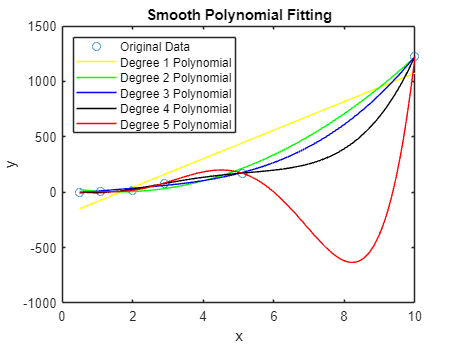


% Plot the original data and the fitted polynomials
figure;
plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;
plot(X, y_fit1, 'y-', 'DisplayName', 'Degree 1 Polynomial');
plot(X, y_fit2, 'g-', 'DisplayName', 'Degree 2 Polynomial');
plot(X, y_fit3, 'b-', 'DisplayName', 'Degree 3 Polynomial');
plot(X, y_fit4, 'k-', 'DisplayName', 'Degree 4 Polynomial');
plot(X, y_fit5, 'r-', 'DisplayName', 'Degree 5 Polynomial');
hold off;

% Add labels and legend
xlabel('x');
ylabel('y');
title('Smooth Polynomial Fitting');
legend('show','Location','northwest');

## Problem 4 Least-Square Fit

% 
% Define x values
x = linspace(1, 10, 10);

% Calculate y values
y = 2 * x;

% Number of data points
N = length(x);

% Construct matrix A
A = [sum(x.^3), sum(x.^(3/2)); 
     sum(x.^(5/2)), sum(x)];

% Calculate the vector f
f = [sum(x .* y); sum(y .* x.^0.5)];

% Calculate the inverse of A
A_inv = inv(A);

% Solve for coefficients c
c = A_inv * f;


fprintf('Problem #4')

Problem #4


% Extract coefficients a and b
a = c(1)

a = 0.1173

b = c(2)

b = 2.9091


% Generate X values for plotting
X = linspace(1, 10, 1000);

% Calculate corresponding Y values
Y = a * X.^2 + b * X.^0.5;

% Calculate Y values for the original data points
Y_plot = a * x.^2 + b * x.^0.5;

% Calculate standard deviation of y
std_y = sqrt(sum((y - Y_plot).^2) / (N - 2))

std_y = 0.6646

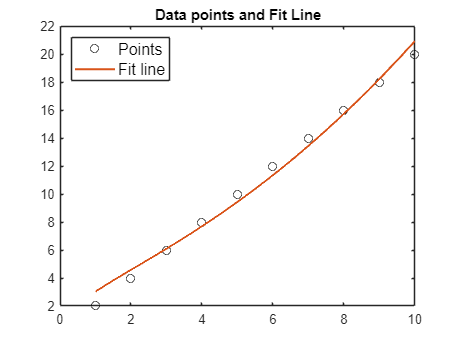


% Plot the results
figure;
plot(x, y, 'ko','DisplayName', 'Points');
hold on;
plot(X, Y, 'linewidth', 1.5','DisplayName', 'Fit line');
title('Data points and Fit Line');
legend('fontsize', 12, 'Location','northwest');
hold off;